# Maze identifier

This will import the chosen maze 'simple_maze.png' for solving and convert it to a usable format.

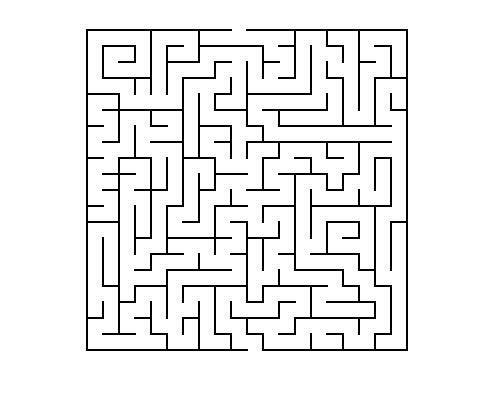

%Open up a maze, with walls designated as ones and zeroes
close all
clear all
maze = imread('simple_maze.png');

hsvmaze = rgb2hsv(maze);
binmaze = hsvmaze(:,:,3) >= 0.3;

imshow(binmaze)

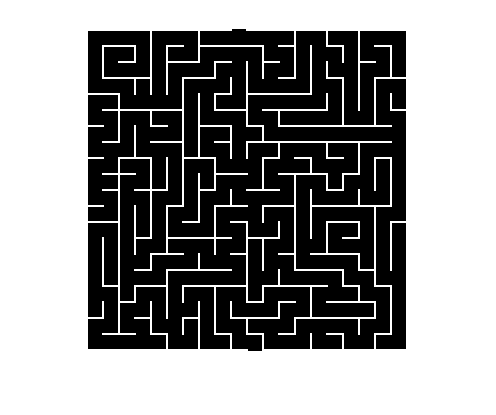


%Fill the entire assageways with life
A = binmaze==0;

imshow(A)

## The values below are the Chosen start and end co-ordinate for 'simple_maze.png'.


start_x = 150;
start_y = 1;
end_x = 170;
end_y = 320;


## Initialisation

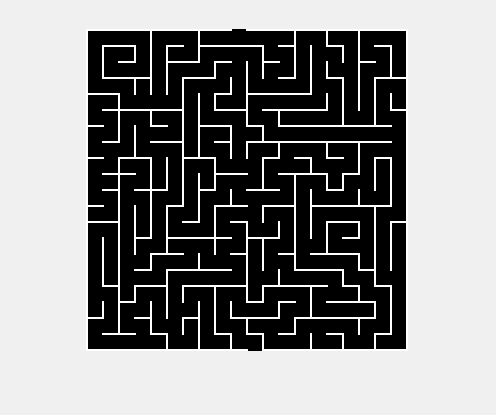

close all

mapdim = size(A);
R = mapdim(1);  % number of rows
C = mapdim(2);  % number of columns

%For the indices below, I couldn't get 
north = [R,1:R-1];     % indices of north neighbour
south = [2:R,1];       % indices of south neighbour
west  = [C,1:C-1];     % indices of west neighbour
east  = [2:C,1];       % indices of east neighbour

% Show the initial frame in the animation
set(figure, 'Visible', 'on', 'Position', get(0,'Screensize'));
%handle = imshow(A, 'InitialMagnification', 'Fit'); % save the handle for when we want to update the image later
imshow(A)

%% Simulation
i=1

i = 1

done = false;
while done == false 
     B=A;
i=i+1;


    % Count how many of the cells on each cardinal corner are dead cells
    
NE_corner_condition = A(north, :)+ A(:, east) + A(north,east);
NW_corner_condition = A(north, :)+ A(:, west) + A(north,west);
SE_corner_condition = A(south, :)+ A(:, east) + A(south,east);
SW_corner_condition = A(south, :)+ A(:, west) + A(south,west);
    
    is_an_outside_corner =(A==0) & (...
 (A(south,:)==true &A(:, west)==true & A(south,west)==true )  ...   %     n 1 1
|(A(south, :)==true & A(:, east) ==true & A(south,east)==true)...     %     n 0 1   <--Some rotation of this
|(A(north, :)==true & A(:, west)==true & A(north,west)==true)...     %     n n n    
|(A(north, :)==true & A(:, east)==true & A(north,east)==true));

    
    is_an_inside_corner =  (A==0)&(...
  (A(south, :)==false & A(:, west)==false & A(south,west)==true)  ...  %     n n n
| (A(south, :)==false & A(:, east) ==false & A(south,east)==true)...     %     0 0 n   <--Some rotation of this
| (A(north, :)==false & A(:, west)==false & A(north,west)==true)...     %     1 0 n 
| (A(north, :)==false & A(:, east)==false & A(north,east)==true))...
& ( NE_corner_condition == 3 |  NW_corner_condition ==3 |  SE_corner_condition ==3 |  SW_corner_condition==3);
                                                                            
    is_single =  (A==0)&(...
  (A(south, :)==false & A(:, west)==false & A(south,west)==true)  ...  %     n n n
| (A(south, :)==false & A(:, east) ==false & A(south,east)==true)...     %     0 0 n   <--Some rotation of this
| (A(north, :)==false & A(:, west)==false & A(north,west)==true)...     %     1 0 n 
| (A(north, :)==false & A(:, east)==false & A(north,east)==true));
                                                
     is_line =  (A==0)&(...
  (A(south, :)==false & (A(north, :)==false | A(north, east) ==false | A(north, west)==false)) ...                                                    %     n n n
| (A(:, west))==false & (A(:, east) ==false | A(north, east)==false | A(south, east)==false)) ...                         %    0 0 0   <--Some rotation of this
| (A(north, west)==false & A(south, east)==false) ...                                                                                                           %   n n n 
| (A(north, east)==false  & A(south, west)==false);
                                                     
                                                 
    should_die = ((is_an_outside_corner == true) &  (is_an_inside_corner==false))  & (is_line==false);%| is_single;
    
    % These two rules determine the new state of every element
    A = A + should_die;
    A(start_y, start_x)=0;
    A(end_y, end_x)=0;
    
  
    %imshow(A)

    if all(B==A)
        done=true;
    end
    
end  

## solved maze

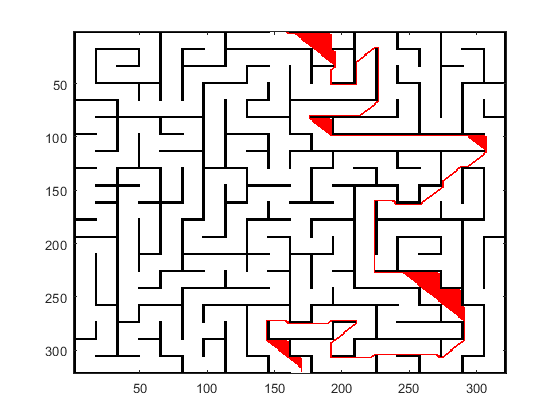

%Create a red path

pathline = 255.*(uint8(~A));
%imshow(pathline)
tracedmaze=maze;
tracedmaze(:, :, 2:3)=tracedmaze(:, :, 2:3)-pathline;
%tracedmaze(:,:,1)=maze(:,:,1)+pathline

figure
   imagesc(tracedmaze);

This will import the chosen maze 'gordan.jpg' for solving and convert it to a usable format.

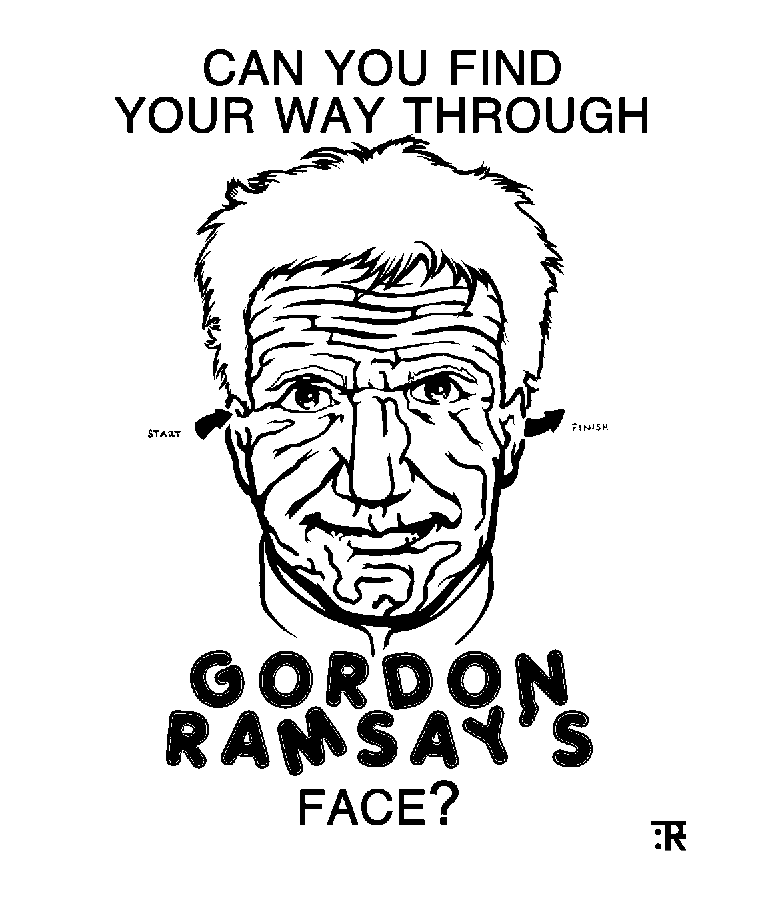

%Open up a maze, with walls designated as ones and zeroes
close all
clear all
maze = imread('gordan.jpg');

hsvmaze = rgb2hsv(maze);
binmaze = hsvmaze(:,:,3) >= 0.3;

imshow(binmaze)

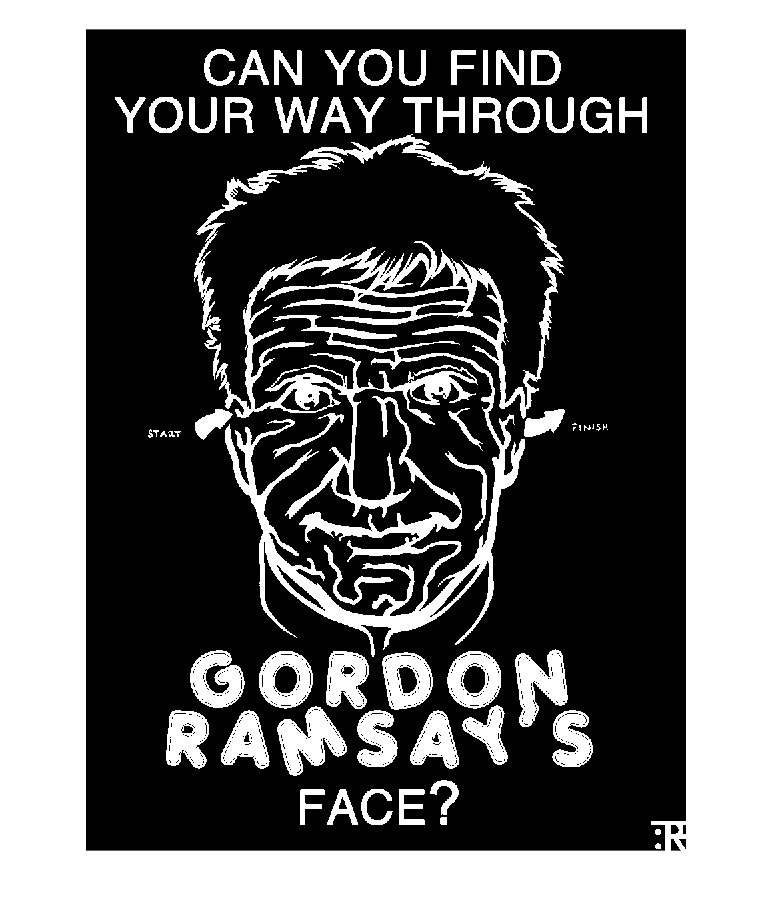


%Fill the entire assageways with life
A = binmaze==0;

imshow(A)

## The values below are the Chosen start and end co-odinate for 'gordan'.

start_x = 220;
start_y = 580;
end_x = 650;
end_y = 600;

## Initialisation

close all

mapdim = size(A);
R = mapdim(1);  % number of rows
C = mapdim(2);  % number of columns

north = [R,1:R-1];     % indices of north neighbour
south = [2:R,1];       % indices of south neighbour
west  = [C,1:C-1];     % indices of west neighbour
east  = [2:C,1];       % indices of east neighbour

% Show the initial frame in the animation
%set(figure, 'Visible', 'on', 'Position', get(0,'Screensize'));
%handle = imshow(A, 'InitialMagnification', 'Fit'); % save the handle for when we want to update the image later
%imshow(A)

%% Simulation

i=1;
done = false;
while done == false
    B=A;
    i=i+1;
    if i==95
        i=1;
    end 

    % Count how many of the cells on each cardinal corner are dead cells
    
NE_corner_condition = A(north, :)+ A(:, east) + A(north,east);
NW_corner_condition = A(north, :)+ A(:, west) + A(north,west);
SE_corner_condition = A(south, :)+ A(:, east) + A(south,east);
SW_corner_condition = A(south, :)+ A(:, west) + A(south,west);
    
    is_an_outside_corner =(A==0) & (...
 (A(south,:)==true &A(:, west)==true & A(south,west)==true )  ...   %     n 1 1
|(A(south, :)==true & A(:, east) ==true & A(south,east)==true)...     %     n 0 1   <--Some rotation of this
|(A(north, :)==true & A(:, west)==true & A(north,west)==true)...     %     n n n    
|(A(north, :)==true & A(:, east)==true & A(north,east)==true));

    
    is_an_inside_corner =  (A==0)&(...
  (A(south, :)==false & A(:, west)==false & A(south,west)==true)  ...  %     n n n
| (A(south, :)==false & A(:, east) ==false & A(south,east)==true)...     %     0 0 n   <--Some rotation of this
| (A(north, :)==false & A(:, west)==false & A(north,west)==true)...     %     1 0 n 
| (A(north, :)==false & A(:, east)==false & A(north,east)==true))...
& ( NE_corner_condition == 3 |  NW_corner_condition ==3 |  SE_corner_condition ==3 |  SW_corner_condition==3);
                                                                            
    is_single =  (A==0)&(...
  (A(south, :)==false & A(:, west)==false & A(south,west)==true)  ...  %     n n n
| (A(south, :)==false & A(:, east) ==false & A(south,east)==true)...     %     0 0 n   <--Some rotation of this
| (A(north, :)==false & A(:, west)==false & A(north,west)==true)...     %     1 0 n 
| (A(north, :)==false & A(:, east)==false & A(north,east)==true));
                                                
     is_line =  (A==0)&(...
  (A(south, :)==false & (A(north, :)==false | A(north, east) ==false | A(north, west)==false)) ...                                                    %     n n n
| (A(:, west))==false & (A(:, east) ==false | A(north, east)==false | A(south, east)==false)) ...                         %    0 0 0   <--Some rotation of this
| (A(north, west)==false & A(south, east)==false) ...                                                                                                           %   n n n 
| (A(north, east)==false  & A(south, west)==false);
                                                     
                                                 
    should_die = ((is_an_outside_corner == true) &  (is_an_inside_corner==false))  & (is_line==false);%| is_single;
    
    % These two rules determine the new state of every element
    A = A + should_die;
    A(start_y, start_x)=0;
    A(end_y, end_x)=0;
    
  
    %imshow(A)

    if all (B==A)
        done=true;
    end
    
    %handle.CData = ~A;  % this is a faster way to update the existing image, rather than redraw it with imshow
end

## solved maze

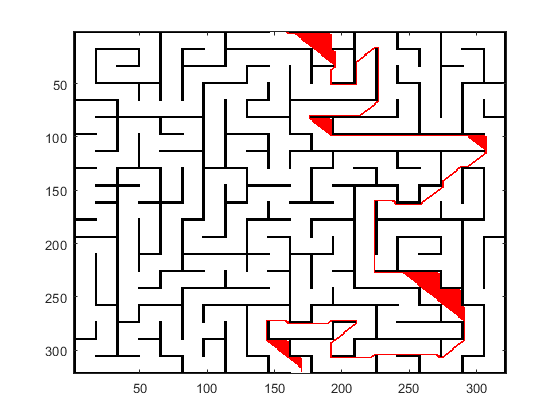

%Create a red path

pathline = 255.*(uint8(~A));
%imshow(pathline)
tracedmaze=maze;
tracedmaze(:, :, 2:3)=tracedmaze(:, :, 2:3)-pathline;
%tracedmaze(:,:,1)=maze(:,:,1)+pathline

   imagesc(tracedmaze)

%%Errors and Notes%%

% We have two warning in code both are about CLEAR ALL slowing down the code.
% This is acceptable as it insures a clean start for each of the mazes.

% Both mazes